# Principal Component Analysis    

## 2D

% Load 2D mesh
mesh = load_mesh('circle2000_86_stnd');

Fixed sources
Sources integration functions loaded
Fixed detectors
Detectors integration functions loaded


Elapsed time is 1.692629 seconds.



plotmesh_fiducials(mesh), axis off;

% Check if the file exists
if exist('var/jacobian/2D.mat') == 2
    % File exists, so you can skip running the code or add code here
    disp('File found. Skipping jacobian calculation');
else
    % File doesn't exist, so you can run your code here
    disp('File not found. Calculating jacobian...');

    % Calculate Jacobian at 0 MHz, i.e. CW case
    % This is only for Amplitude data and mua only
    J = jacobian_FD(mesh,0);
    
    % Keep only complete part!
    J = rmfield(J,'complex');
    
    save var/jacobian/2D J -V7.3
        
end

%% Mesh Blob
%% Model activation 5 mm radius in gray matter only
activation_centre_1 = [20 20];

activation_centre_2 = [0, -20];

activation_centre_3 = [-25, 20];

blob_indx_1 = find(sqrt(sum((mesh.nodes-activation_centre_1).^2,2))<=5);

blob_indx_2 = find(sqrt(sum((mesh.nodes-activation_centre_2).^2,2))<=5);

blob_indx_3 = find(sqrt(sum((mesh.nodes-activation_centre_3).^2,2))<=5);

blob_indx = union(blob_indx_1, union(blob_indx_2, blob_indx_3));

% set label for viewing
mesh_blob = mesh;
mesh_blob.region(blob_indx) = 3;

delta_mua = zeros(size(J.complete,2),1);
delta_mua(blob_indx) = 1;

% Plot 2D blob
% plotimage(mesh_blob,mesh_blob.region);

% Calculate Up(nxp)
Up = PCA(J.complete, 50);

Size of Up: [1785, 50]


% Transform Jacobian and delta_mua
Y = J1 * Up;
delta_mua_p = Up' * delta_mua1;

tic
rhs = Y * delta_mua_p;

%% reconstruct from simulated data
Hess = Y * Y';
reg = eye(size(Hess)).*max(diag(Hess)).*1e-1;

mua_recon_p = Y'*inv(Hess+reg)*rhs;
toc

Elapsed time is 0.015423 seconds.


mua_recon = Up * mua_recon_p;

% Create a zero vector of the same size as the original 'delta_mua'
reconstructed_delta_mua = zeros(1, length(delta_mua));

% Place the selected values at their respective indices
reconstructed_delta_mua(selected_indices) = mua_recon;


plotimage(mesh,reconstructed_delta_mua);

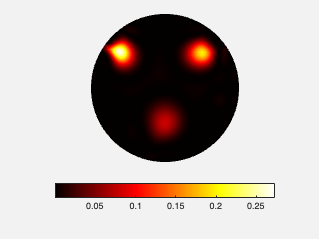

mua_recon_sq = mua_recon .^ 2;
plotimage(mesh,mua_recon_sq);

## 3D

% Load 3D mesh
load meshes/subject10_stnd.mat


Elapsed time is 47.832703 seconds.


% plot 3D mesh
% figure, plotmesh_fiducials(mesh), axis off;

% Check if the file exists
if exist('var/jacobian/brain.mat') == 2
    % File exists, so you can skip running the code or add code here
    disp('File found. Skipping jacobian calculation');
else
    % File doesn't exist, so you can run your code here
    disp('File not found. Calculating jacobian...');

    % Calculate source/detector separation
    SDS = sqrt(sum((mesh.source.coord(mesh.link(:,1),:)-mesh.meas.coord(mesh.link(:,2),:)).^2,2));
    
    % use only channel (source/detector separations) distance of <35 mm
    indx = find(SDS<=35);
    mesh.link = mesh.link(indx,:);
    
    % Calculate Jacobian at 0 MHz, i.e. CW case
    % This is only for Amplitude data and mua only
    J = jacobian_FD(mesh,0);
    
    % Keep only complete part!
    J = rmfield(J,'complex');
    
    save var/jacobian/brain J -V7.3
        
end


%% Mesh blob
%% Model activation 10 mm radius in gray matter only
activation_centre = [103 132 157];

blob_indx = find(sqrt(sum((mesh.nodes-activation_centre).^2,2))<=20);
gray_indx = find(mesh.region==4);
blob_indx = intersect(blob_indx,gray_indx);

% set label for viewing
mesh_blob = mesh;
mesh_blob.region(blob_indx) = 20;

delta_mua = zeros(size(J.complete,2),1);
delta_mua(blob_indx) = 1;

% Thresholding
tic
row_sum = sum(J.complete, 1);
threshold_percent = 1; % sensitivity threshold
max_value = max(abs (row_sum));
threshold = max_value * threshold_percent / 100;
selected_indices = find(abs (row_sum) >= threshold);
J1 = J.complete(:, selected_indices);
delta_mua1 = delta_mua(selected_indices);
toc

Elapsed time is 1.936043 seconds.


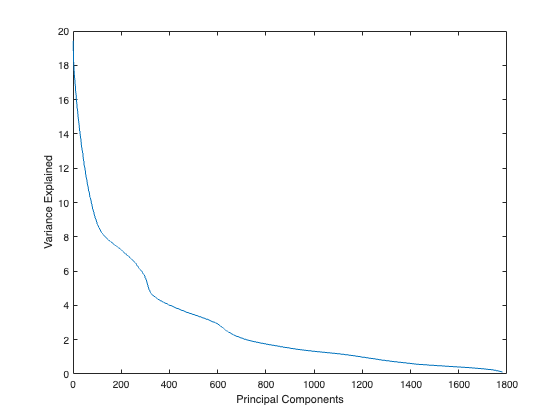

Size of Up: [131415, 600]


Elapsed time is 0.853319 seconds.


Up = PCA(J1, 600);

% Transform Jacobian and delta_mua
Y = J1 * Up;
delta_mua_p = Up' * delta_mua1;

Elapsed time is 2.794320 seconds.


tic
rhs = Y * delta_mua_p;

%% reconstruct from simulated data
Hess = Y * Y';
reg = eye(size(Hess)).*max(diag(Hess)).*1e-1;

mua_recon_p = Y'*inv(Hess+reg)*rhs;
toc

Elapsed time is 0.329409 seconds.


mua_recon = Up * mua_recon_p;

% Create a zero vector of the same size as the original 'delta_mua'
reconstructed_delta_mua = zeros(1, length(delta_mua));

% Place the selected values at their respective indices
reconstructed_delta_mua(selected_indices) = mua_recon;

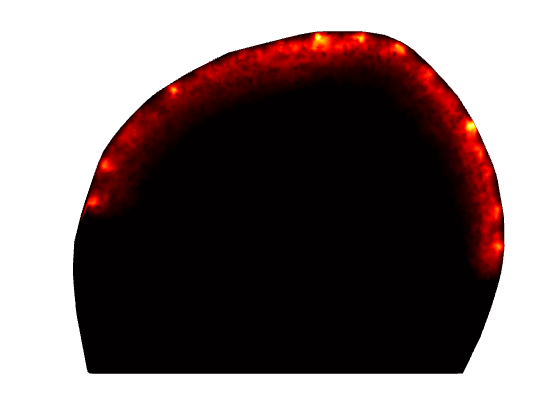


% Mua Recon Viz
[xgrid,ygrid,zgrid] = meshgrid(26:0.05:216, 1:0.05:151, 157);
delta_mua_interp = griddata(mesh.nodes(:,1),mesh.nodes(:,2),mesh.nodes(:,3),reconstructed_delta_mua,xgrid(:),ygrid(:),zgrid(:));
delta_mua_1 = reshape(delta_mua_interp,size(xgrid));
set(groot, 'DefaultSurfaceEdgeColor', 'none')
figure,pcolor(squeeze(delta_mua_1)'),colormap hot,axis xy equal tight, axis off, camroll(90);

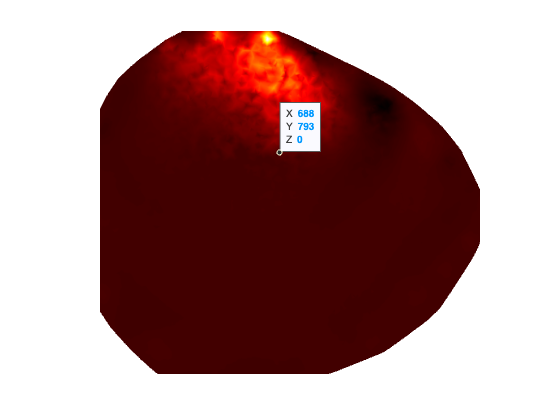

[xgrid,ygrid,zgrid] = meshgrid(47:0.1:182, 132, 68:0.1:190);
delta_mua_interp = griddata(mesh.nodes(:,1),mesh.nodes(:,2),mesh.nodes(:,3),reconstructed_delta_mua,xgrid(:),ygrid(:),zgrid(:));
delta_mua_2 = reshape(delta_mua_interp,size(xgrid));
set(groot, 'DefaultSurfaceEdgeColor', 'none')
figure,pcolor(squeeze(delta_mua_2)'),colormap hot,axis xy equal tight, axis off;